clc, clear
Time = 5;
Fs = 40;
N = Time*Fs;
a = strings(N,1);

s = serialport("COM3",57600);
configureTerminator(s,"CR/LF");
for i = 1:N
    a(i,:) = readline(s);
end
b = double(a);
Data = b;
clear s

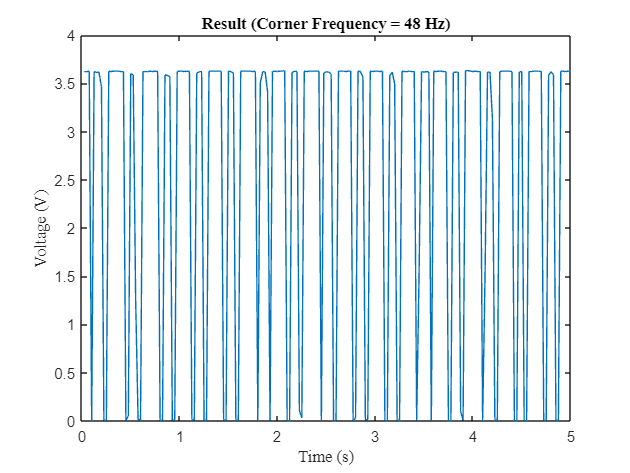

close all
syms t s
b1 = b/1023*5;
tt = 1/Fs : 1/Fs : Time;
plot(tt, b1)
title("Result (Corner Frequency = 48 Hz)", "FontName", "Times New Roman");
xlabel("Time (s)", "FontName", "Times New Roman");
ylabel("Voltage (V)", "FontName", "Times New Roman");


Y=fft(b1-2.5)

Y =   25.0293 + 0.0000i
  -5.4640 + 0.3210i
   3.1267 + 4.9895i
   9.8377 -10.7485i
   7.4555 + 0.8344i
   3.1174 + 1.6757i
  15.6940 - 7.5388i
  -1.6807 - 0.0500i
   3.7708 + 4.5465i
  -2.8886 -18.6588i


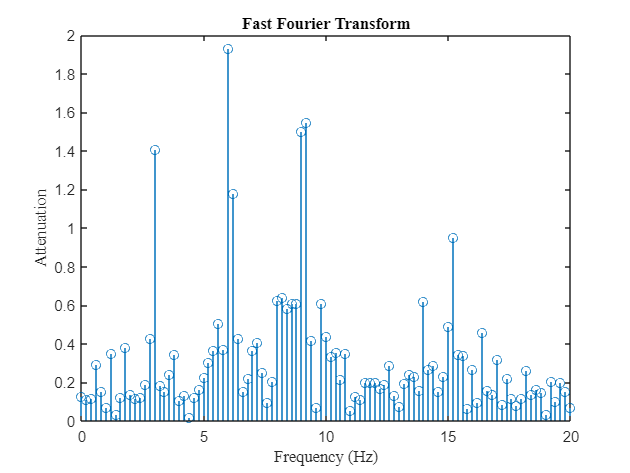


Y(1) = Y(1)/2;
P2 = abs(Y/(N/2));
P1 = P2(1:N/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = Fs*(0:(N/2))/N;
% fig2 = figure("Name","a");
stem(f,P1)
title("Fast Fourier Transform", "FontName", "Times New Roman");
xlabel("Frequency (Hz)", "FontName", "Times New Roman");
ylabel("Attenuation", "FontName", "Times New Roman");

% set(fig2, 'Units', 'Inches');
% set(fig2, 'Position', [0, 0, 10, 4]);
% set(fig2, 'PaperPositionMode', 'auto');
% exportgraphics(fig2, 'FFT_Assignemt2.png', 'Resolution', 600);